## **EEE4119F - PRACTICAL 3:**

## **Ronak Mehta [*****MHTRON001*****]     and    Vacquero Augustine [*****AGSVAC001*****] **

Question 1 - Euler:

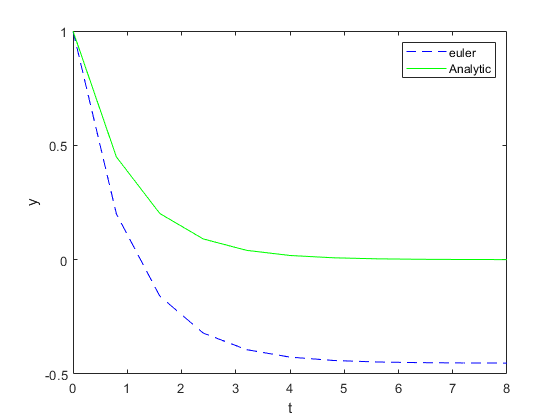

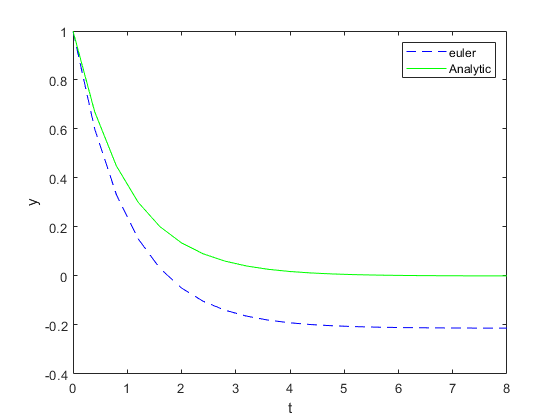

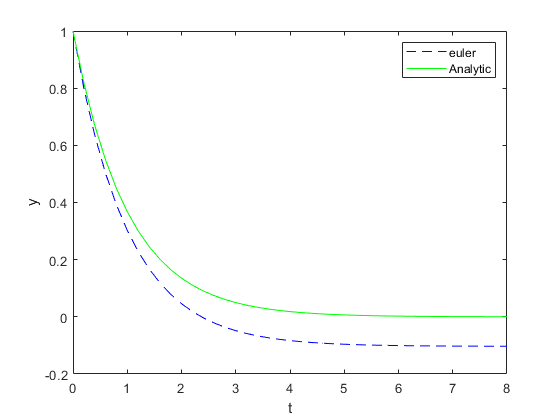

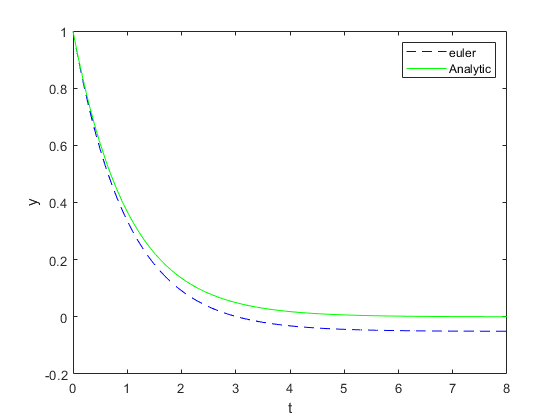

%This code covers Question 1 and its sub-questions
%When the program is run it produces 4 plots
%Each plot corresponds to a time step dt
%The first plot is a time step dt = 0.8
%The last plot is a time step dt= 0.1

time_step = [0.8,0.4,0.2,0.1]; %Time steps dt

for p = time_step %This part runs through each time step dt
    
    [t,y] = euler1stOrder(1,@deriv,p,8); %Calls function to integrate given ODE
    
    g = exp(-t); %Analytical solution
    figure()
    plot(t,y,'b--'); %Plot Numerical solution (Euler) 
    hold on
    
    plot(t,g,'g'); %Plot analytical solution
    hold off
    
    xlabel('t');
    ylabel('y');
    legend('euler','Analytic');
end

Question 2 - Runge Kutta 4 [RK4]:

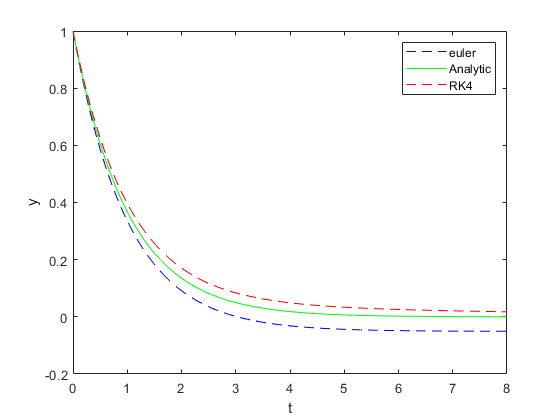

%This code covers Question 2 and its sub-questions
%When the program is run it produces 4 plots
%Each plot corresponds to a time step dt
%The first plot is a time step dt = 0.8
%The last plot is a time step dt= 0.1

time_step = [0.8,0.4,0.2,0.1];

for p = time_step %This part runs through each time step dt
    [t,y] = euler1stOrder(1,@deriv,p,8);%Calls function to integrate given ODE
    [t,g] = runge_kutta_4(1,@deriv,p,8);%Calls function to integrate given ODE
    
    end
    figure()
    plot(t,y,'b--');%Plot Numerical solution (Euler) 
    hold on
    
    z = exp(-t); %Analytical solution
    plot(t,z,'g');%Plot analytical solution
    
    plot(t,g,'r--');%Plot Numerical solution (RK4) 
  
    hold off
    
    xlabel('t');
    ylabel('y');
    legend('euler','Analytic','RK4');

Question 3 - built-in solver:

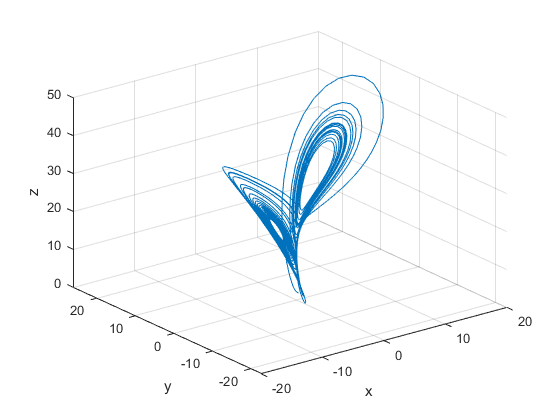

%This code covers Question 3 and its sub-questions
%When the program is run it produces 1 plot

options = odeset('AbsTol',1e-6);%set the absolute tolerance of the option solver 
tspan = [0,30]; % Time span
y0 = [1,1,1]; %Initial condition

[t, y] = ode45(@Lorenz, tspan, y0, options); %Call ODE45 function

plot3(y(:,1),y(:,2),y(:,3)); %plot solution
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

Question 4 - basic symbolic simplification:

% Qn 4a:
syms x y;
simplify((sin (x))^2 + (cos (x))^2) % LHS of the equation

$$ans = 1$$

    
% Qn 4b:
syms x y;
simplify(cos(y)*sin(x) + cos(x)*sin(y)) %LHS of the equation

$$ans = \sin\left(x+y\right)$$

simplify(cos(y)*sin(x) + cos(x)*sin(y)) == expand(sin(x+y))

$$ans = \sin\left(x+y\right)=\cos\left(x\right)\,\sin\left(y\right)+\cos\left(y\right)\,\sin\left(x\right)$$

    
% Qn 4c:
syms x y;
simplify((cosh (x))^2 - (sinh (x))^2) % LHS of the equation

$$ans = 1$$

Question 5 - solve a simple equation:

% Qn 5a:
syms a b c A
E = ((b^2) + (c^2) - (2*b*c*cos(A)) == (a^2));
b_ans = solve(E,b)

$$b\_ans = \left(\begin{array}{c} c\,\cos\left(A\right)+\sqrt{a^{2}+c^{2}\,{\cos\left(A\right)}^{2}-c^{2}}\\ c\,\cos\left(A\right)-\sqrt{a^{2}+c^{2}\,{\cos\left(A\right)}^{2}-c^{2}} \end{array}\right)$$

% //Another way
%solve(((b^2) + (c^2) - (2*b*c*cos(A)) == (a^2)),b) 

% Qn 5b:
syms m
F = subs(E,{a,c,A},{(5*m),(2*m),(pi/3)})

$$F = b^{2}-2\,b\,m+4\,m^{2}=25\,m^{2}$$

b_ans = solve(F,b)

$$b\_ans = \left(\begin{array}{c} m+\sqrt{22}\,m\\ m-\sqrt{22}\,m \end{array}\right)$$

Question 6 - symbolic pole placement:

syms s k1 k2
sI = eye(2)*s;
A = [0 -1;5 2];
b = [0;1];
K = [k1, k2];

X = sI -A + (b*K)

$$X = \left(\begin{array}{cc} s & 1\\ k_{1}-5 & k_{2}+s-2 \end{array}\right)$$

eq1 = det(X)                %Characterstic Equation

$$eq1 = k_{2}\,s-2\,s-k_{1}+s^{2}+5$$

s_coeff_eq1 = coeffs(eq1,s)

$$s\_coeff\_eq1 = \left(\begin{array}{ccc} 5-k_{1} & k_{2}-2 & 1 \end{array}\right)$$


eq2 = expand((s+5)*(s+10))  %Pole Placement Equation

$$eq2 = s^{2}+15\,s+50$$

s_coeff_eq2 = coeffs(eq2,s)

$$s\_coeff\_eq2 = \left(\begin{array}{ccc} 50 & 15 & 1 \end{array}\right)$$


Y = coeffs((eq1 - eq2),s);
K1 = solve(Y(1),k1)

$$K1 = -45$$

K2 = solve(Y(2),k2)

$$K2 = 17$$

Functions

function [t,y] = euler1stOrder(y0, f, dt, t_final)
steps = round((t_final)/dt); %Number of steps to take
y = zeros(1,steps+1); %Sets up an array to hold Numerical solution
y(1)=y0; %Initial condition
t = 0:dt:t_final;
x = exp(-t);
dy = feval(f,t,x); %Evaluates function at given point

for i=1:steps
    
    y(i+1)= y(i)+dt*dy(i); %Integration
end
end

function dy = deriv(time,y)
dy = zeros(length(y));
dy = -y; %Obtains derivative at specific value for t
end

function [t, g] = runge_kutta_4(y0, f, dt, t_final)
y = y0;%Initial condition
steps = round((t_final)/dt); %Number of steps to take
g = zeros(1,steps+1);  %Sets up an array to hold Numerical solution
g(1)=y0; %Initial condition
t = 0:dt:t_final;
x = y0;

for i= 1:steps
    %The following are the four terms used in the RK4 method
    k1 = -x;
    h_ts = dt/2;
    k2 = feval(f,t(i),exp(-t(i)- h_ts) + dt*k1/2);
    k3 = feval(f,t(i),exp(-t(i)-h_ts) + dt*k2/2);
    k4 = feval(f,t(i),exp(-t(i)-dt)+ dt*k3);

    g(i+1) = g(i) + dt*((k1+2*k2+2*k3+k4)/6); %Integration
    x = g(i+1); %Updates the current value of y
end
end


function [dy] = Lorenz(time,y) %Lorenz function
dy = zeros(3)'; %Sets up an array to hold Lorenz ODE's
dy = [10*(y(2)-y(1)),y(1)*(27-y(3))-y(2),y(1)*y(2)-(8*y(3))/3]';
end